Să se studieze condiționarea rădăcinilor multiple ale polinomului:


$$(x-1)^2(x-2)^2...(x-n)^2 = 0$$


Dezvoltam fiecare termen:


$$(x-1)^2(x-2)^2...(x-n)^2 = 0 \Rightarrow (x^2-2x+1)(x^2-4x+4)...(x^2-2nx+n^2) = 0$$


$a*x^2 + bx + c = (x^2-2x+1)(x^2-4x+4)...(x^2-2nx+n^2)$:

- $a = 1 + 1 + ... + 1 = n$;

- $b = -2-4-6-...-2n = -2 * (1 + 2 + 3 + ... + n) = -n(n+1)$;

- $c = 1 + 4 + 9 + ... + n^2 = \frac{n(n+1)(2n+1)}{6}$;


$$\Rightarrow nx^2 -n(n+1)*x + \frac{n(n+1)(2n+1)}{6} = 0$$


Pentru n > 1, polinomul nu are solutii reale. Numarul de conditionare al radacinilor este in termen de 1e-4, astfel perturbari minore in input nu vor afecta foarte mult output-ul.

clear; clc; close all;
format compact;
n = 20;

mean = 0;
sigma = 1e-10;

lower_bound_unif = 1e-11;
upper_bound_unif = 1e-10;

% (x-1)^2(x-2)^2...(x-n)^2 = 0
roots_poly_ = quad_roots(n)

roots_poly_ =   10.5000 - 5.7663i  10.5000 + 5.7663i


poly_ = poly(roots_poly_)

poly_ =     1.0000  -21.0000  143.5000


nc = root_cn(poly_, roots_poly_)

nc = 	1.0e+-4 *

    0.1832    0.1832


figure(1);
hold on;
grid on;

scatter(real(roots_poly_), imag(roots_poly_), 100, 'filled', 'r', 'o', 'DisplayName', 'No perturbation');
% ### DISTRIBUTIE NORMALA
norm_poly = poly_ + normrnd(mean, sigma, 1, 3);
try
    norm_poly_roots = roots(norm_poly)'
    scatter(real(norm_poly_roots), imag(norm_poly_roots), 50, 'filled', 'b', 'o', 'DisplayName', 'Norm perturbation');
catch e
    fprintf("Perturbare normala a intampinat o eroare: %s\n", e.message);
end

norm_poly_roots =   10.5000 - 5.7663i  10.5000 + 5.7663i


% ### DISTRIBUTIE UNIFORMA
unif_poly = poly_ + unifrnd(lower_bound_unif, upper_bound_unif, 1, 3);
try
    unif_poly_roots = roots(unif_poly)'
    scatter(real(unif_poly_roots), imag(unif_poly_roots), 50, 'filled', 'g', 'o', 'DisplayName', 'Unif perturbation');
catch e
    fprintf("Perturbare uniforma a intampinat o eroare: %s\n", e.message);
end

unif_poly_roots =   10.5000 - 5.7663i  10.5000 + 5.7663i


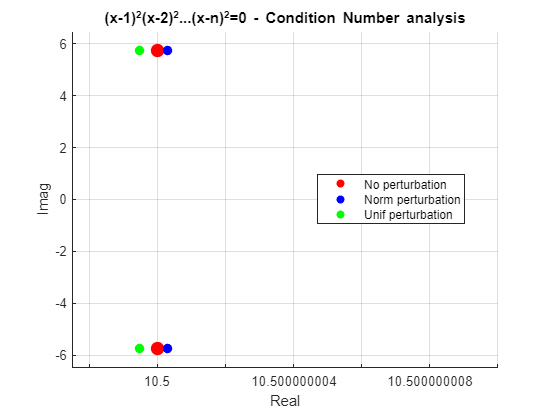

title('(x-1)^2(x-2)^2...(x-n)^2=0 - Condition Number analysis')
legend('Location','best')
xlim([10.4999999975, 10.500000010]);
ylim([-6.5, 6.5]);
xlabel('Real');
ylabel('Imag');
hold off;